Loads and processes data (run everything from utilies)

% fluo, MeanAP
Particles2250 = load('../../dat/1500b_7dT/inference_traces_1500b_7dT_dT7.mat', 'trace_struct_final');
Particles2250 = load('../../dat/2250b_20dT/inference_traces_2250b_20dT_dT20.mat', 'trace_struct_final');

Particles2250 = Particles2250.trace_struct_final;
trace_struct2250 = struct;
idx = 1;
for i = 1:length(Particles2250)
    if length(Particles2250(i).fluo_interp) > 30 && ...
            length(Particles2250(i).cp_frames) / ...
            length(Particles2250(i).all_frames) > 0
        trace_struct2250(idx).fluo = Particles2250(i).fluo_interp;
        trace_struct2250(idx).ap = (.40 - Particles2250(i).MeanAP) * 100;
        idx = idx + 1;
    end
end
% fluo_interp, MeanAP
Particles4700 = load('../../dat/nick_eve2_mhmm/inference_traces_mHMMeve2_weka_inf_2018_05_07_dT20.mat', 'trace_struct_final');
Particles4700 = Particles4700.trace_struct_final;
trace_struct4700 = struct;
idx = 1;
for i = 1:length(Particles4700)
    if length(Particles4700(i).fluo_interp) > 30 && ...
            length(Particles4700(i).cp_frames) / ...
            length(Particles4700(i).all_frames) > 0
        trace_struct4700(idx).fluo = Particles4700(i).fluo_interp;
        trace_struct4700(idx).ap = Particles4700(i).MeanAP;
        idx = idx + 1;
    end
end

Looks at random traces

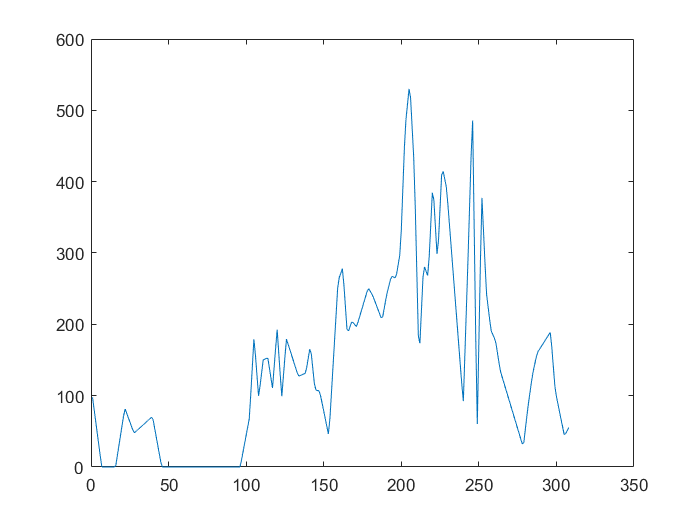

figure();
plot(trace_struct2250(59).fluo);

Compare how many in between points each of them missed

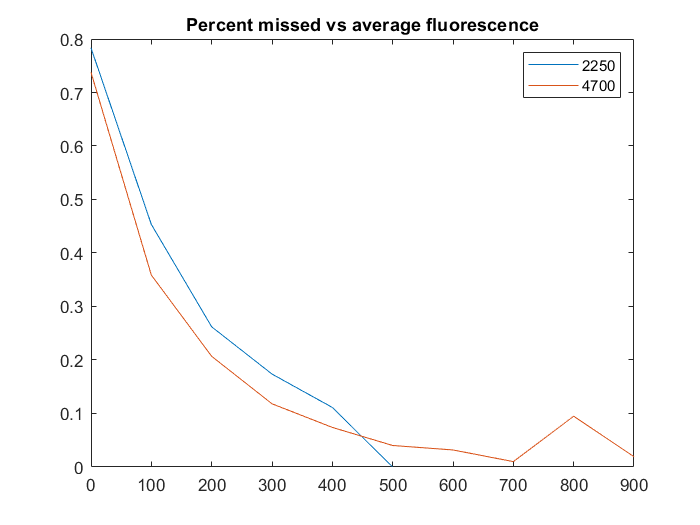

missed2250 = 0;
fluo2250 = 0:100:1200;
miss2250 = zeros(1, length(fluo2250));
counts2250 = zeros(1, length(fluo2250));
for i = 1:length(Particles2250)
    all_len = length(Particles2250(i).all_frames);
    meas_len = length(Particles2250(i).cp_frames);
    missed2250 = missed2250 + (all_len - meas_len) / all_len;
    mean_val = mean(Particles2250(i).fluo_interp);
    [val, idx] = min(abs(mean_val - fluo2250));
    miss2250(idx) = miss2250(idx) + (all_len - meas_len) / all_len;
    counts2250(idx) = counts2250(idx) + 1;
end
missed2250 = missed2250 / length(Particles2250);
miss2250 = miss2250 ./ counts2250;

missed4700 = 0;
fluo4700 = 0:100:1200;
miss4700 = zeros(1, length(fluo4700));
counts4700 = zeros(1, length(fluo4700));
for j = 1:length(Particles4700)
    all_len = length(Particles4700(j).all_frames);
    meas_len = length(Particles4700(j).cp_frames);
    missed4700 = missed4700 + (all_len - meas_len) / all_len;
    mean_val = mean(Particles4700(j).fluo_interp);
    [val, idx] = min(abs(mean_val - fluo4700));
    miss4700(idx) = miss4700(idx) + (all_len - meas_len) / all_len;
    counts4700(idx) = counts4700(idx) + 1;
end
missed4700 = missed4700 / length(Particles4700);
miss4700 = miss4700 ./ counts4700;

figure();
plot(fluo2250, miss2250);
hold on
plot(fluo4700, miss4700);
legend('2250', '4700');
title('Percent missed vs average fluorescence');

Looks at fluorescence content

fluo_distrib2250 = []


fluo_distrib2250 =

     []



fluo_distrib4700 = []


fluo_distrib4700 =

     []



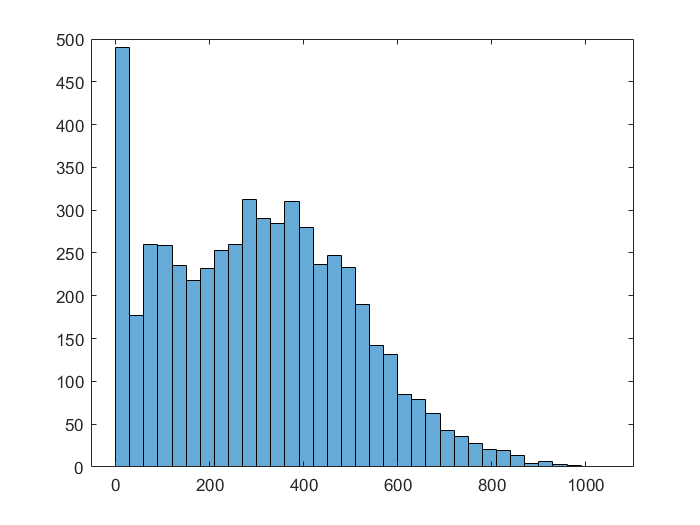


for i = 1:length(trace_struct2250)
    fluo_distrib2250 = [fluo_distrib2250 trace_struct2250(i).fluo];
end

figure();
title('Fluorescnece Distribution 2250bp');
histogram(fluo_distrib2250);

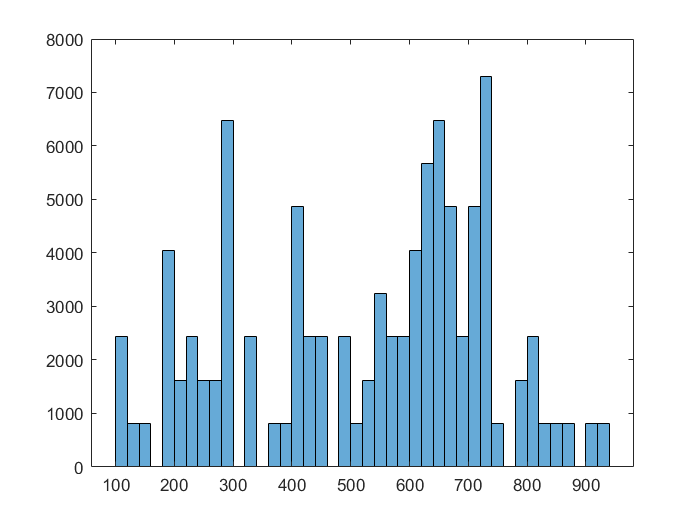


for j = 1:length(trace_struct4700)
    fluo_distrib4700 = [fluo_distrib4700 trace_struct4700(i).fluo];
end

figure();
title('Fluorescnece Distribtion 4700bp');
histogram(fluo_distrib4700);

Preps for autocorrelation and derivatives (and generates them) (run from src)

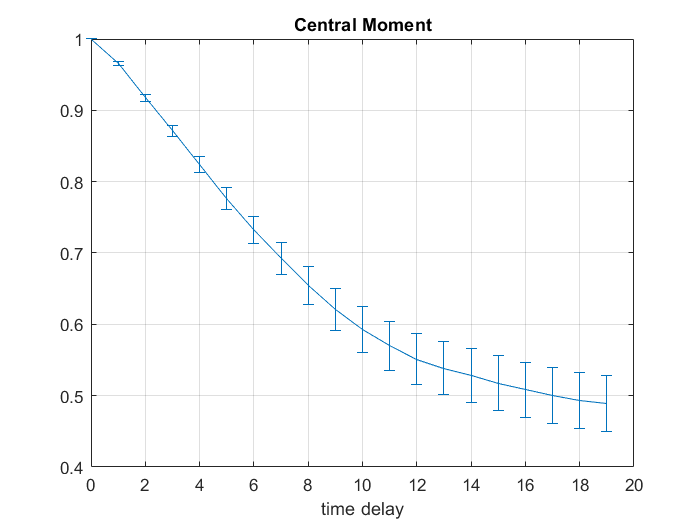

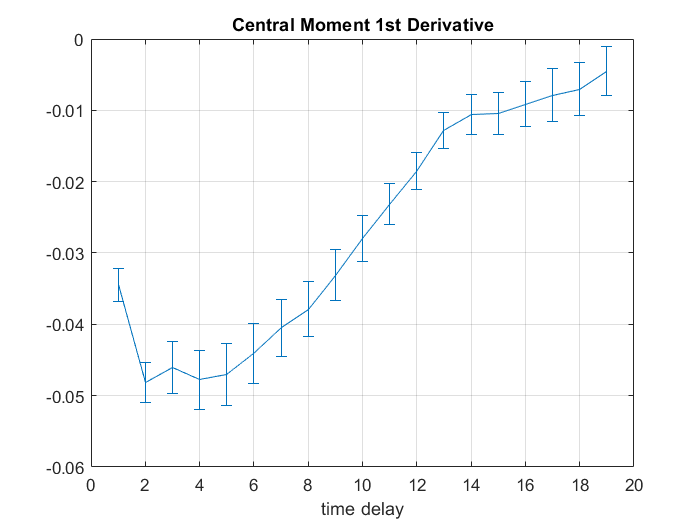

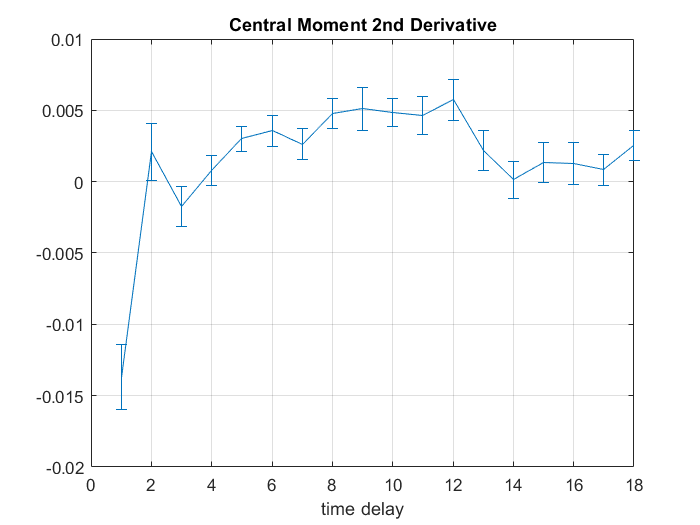

addpath('../')
traces = cell(1, length(trace_struct2250));
for i = 1:length(traces)
    traces{i} = trace_struct2250(i).fluo;
end
gen_auto_cor(traces, true, true, true, true, 20, 0);